clc
clear
RGB = readmatrix('thickness_all\thickness2rgb.csv');
t = RGB(:,1);
r_v = RGB(:,2)/256;
g_v = RGB(:,2)/256;
b_v = RGB(:,3)/256;
xyz_v = rgb2xyz([r_v,g_v,b_v]);

x = 1000;       %薄膜厚度/nm
n = 1.428;      %薄膜折射率
n0 = 1;         %空气折射率
ng = 3.836;     %硅片折射率
i = 0;          %折射角
lambda = 360:830;
x = 1:x;
delta = 4*pi*n*x'*cos(i)./lambda;
R = (n^2*(n0-ng)^2*cos(delta/2).^2+(n^2-n0*ng)^2*sin(delta/2).^2)./...
       (n^2*(n0+ng)^2*cos(delta/2).^2+(n^2+n0*ng)^2*sin(delta/2).^2);
cie = colorMatchFcn('1931_full');
XYZ = R*cie(:,2:4);
xyz_norm = normalize(XYZ,2,'norm',1);
rgb = xyz2rgb(xyz_norm);

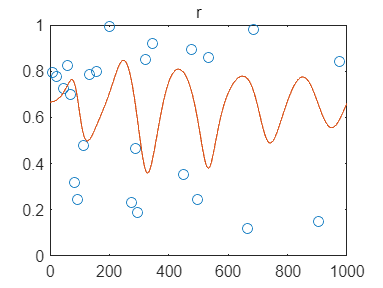

plot(t,r_v,'o')
title('r')
hold on
plot(rgb(:,1))
hold off

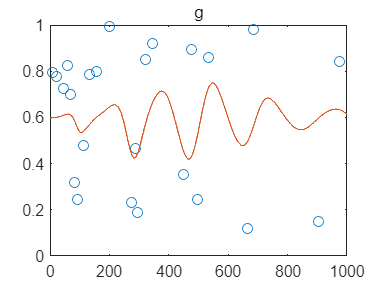

plot(t,g_v,'o')
title('g')
hold on
plot(rgb(:,2))
hold off

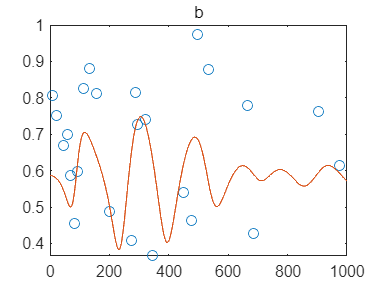

plot(t,b_v,'o')
title('b')
hold on
plot(rgb(:,3))
hold off

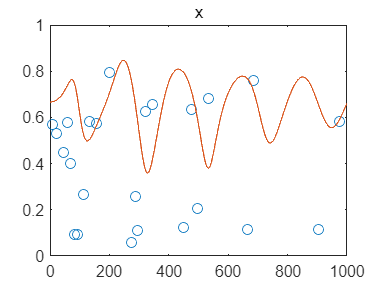

plot(t,xyz_v(:,1),'o')
title('x')
hold on
plot(rgb(:,1))
hold off

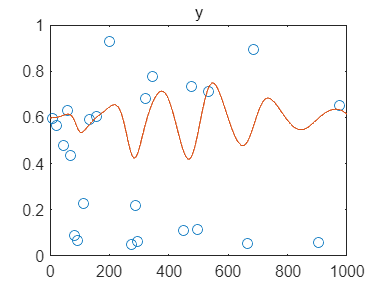

plot(t,xyz_v(:,2),'o')
title('y')
hold on
plot(rgb(:,2))
hold off

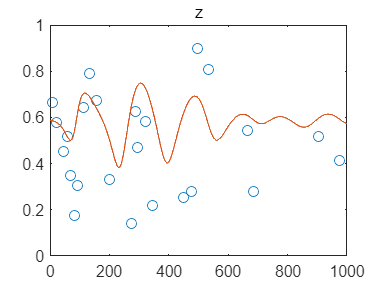

plot(t,xyz_v(:,3),'o')
title('z')
hold on
plot(rgb(:,3))
hold off

model_x = @(b, x) (R.*(b(1)+b(2)*cie(:,1)+b(3)*cie(:,1).^2)'*cie(:,2));
problem = createOptimProblem('lsqcurvefit', ...%优化方法
'objective', model_x, ...%目标函数
'xdata', RGB(:,1), 'ydata', xyz_v(:,1), ...%值
'x0',ones(1,3),...%初始试探值
'lb', [0 0 0],...%参数下限
'ub', [1 1 1]) %参数上限

problem = 包含以下字段的 struct :
    objective: @(b,x)(R.*(b(1)+b(2)*cie(:,1)+b(3)*cie(:,1).^2)'*cie(:,2))
           x0: [1 1 1]
        xdata: [24×1 double]
        ydata: [24×1 double]
           lb: [0 0 0]
           ub: [1 1 1]
       solver: 'lsqcurvefit'
      options: [1×1 optim.options.Lsqcurvefit]


ms = MultiStart;%随机多次优化对象
ms.Display = 'iter';
rng default
[~,fval,exitflag,output,solutions] = run(ms, problem, 100)%尝试50次全局优化

错误使用 lsqcurvefit (第 286 行)
Function value and YDATA sizes are not equal.

出错 globaloptim.multistart.fmultistart

出错 MultiStart/run (第 257 行)
               globaloptim.multistart.fmultistart(problem,startPointSets,msoptions);

原因:
    Failure in call to the local solver with supplied problem structure.